# 滑动平均的等效Fir滤波器

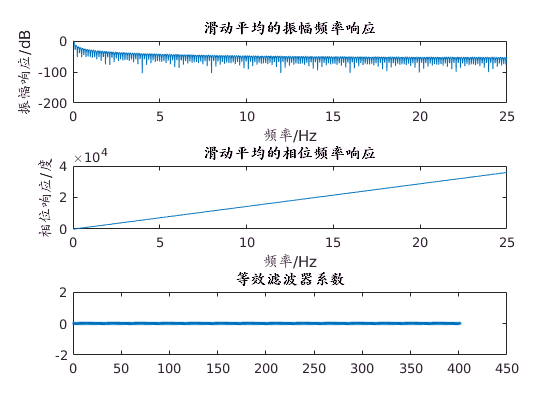

clear all
sliLength=200;
datLength=2*sliLength+1;
Fs=50;
filCloth = zeros(1,datLength);
for i=1:datLength
    filCloth(i)=1/datLength; %滑动平均的等效滤波器系数
end
[ B,theta,f1] = M02_02_firresp_func(filCloth,datLength,Fs);
p=unwrap(theta*pi/180)*180/pi;

figure()
subplot(3,1,1);
plot(f1,B);
xlabel('频率/Hz');
ylabel('振幅响应/dB');
title('滑动平均的振幅频率响应');

subplot(3,1,2);
plot(f1,p);
xlabel('频率/Hz');
ylabel('相位响应/度');
title('滑动平均的相位频率响应')

subplot(3,1,3);
plot(filCloth,'.');
title('滑动平均的等效滤波器系数')